# Regelungssysteme 2

# Programmierpraktikum

# Teil 1: Flugzeugregelung

addpath('functions')

## Linearisiertes Model eines Flugzeuges

Für ein Flugzeug mit Reisegeschwindigkeit Mach 0.8 und einer Höhe von 40.000ft. wird folgendes Zustandsmodell angenommen:


$$\mathbf{\dot{x}} = A \mathbf{x}+B \mathbf{u}
\\
\mathbf{y} = C \mathbf{x}$$


wobei $\mathbf{x} =[\beta \ \omega \ \theta \ \phi]^T$ der Zustandsvektor mit den Zuständen 

- Schiebewinkel $\beta$,

- Giergeschwindigkeit $\omega$,

- Rollgeschwindigkeit $\theta$ und

- Rollwinkel $\phi$

ist. Die Systemmatrix A ist entsprechend eine 4 x 4 Matrix. Die Eingänge sind die Stellung des Seitenruders $u_1$ und der Querruder $u_2$ mit $\mathbf{u}=\text{ }{\left\lbrack u_1 \text{  }u_2 \right\rbrack }^T$ und die zugehörige Eingangsmatrix ist $B=\text{ }{\left\lbrack B_1 \text{  }B_2 \right\rbrack }^T$. Die Ausgänge sind die zeitliche Veränderung des Kurskreisels $y_1$ (= Giergeschwindigkeit) und der Wendezeiger $y_2$ mit $\mathbf{y}=\text{ }{\left\lbrack y_1 \text{ }y_2 \right\rbrack }^T$ und die zugehörige Ausgangssmatrix ist $C=\text{ }{\left\lbrack C_1^T \text{ }C_2^T \right\rbrack }^T$. Weitere Zustände, Eingänge und Ausgänge des Flugzeugs werden nicht betrachtet.

## Aufgabe 1

`Zunächst muss angenommen werden, dass der Pilot das Flugzeug nie zuvor geflogen ist und daher die genauen Parameter der Matrizen A, B und C nicht kennt. Durch seine Erfahrung kennt er aber die grundsätzlichen aerodynamischen Eigenschaften eines Flugzeuges und damit die Struktur der Matrizen`


$$A=\left\lbrack \begin{array}{c}
a_{11}  & a_{12}  & a_{13}  & a_{14} \\
a_{21}  & a_{22}  & a_{23}  & 0\\
a_{31}  & a_{32}  & a_{33}  & 0\\
0 & a_{42}  & a_{43}  & 0
\end{array}\right\rbrack ,B=\left\lbrack \begin{array}{c}
b_{11}  & 0\\
b_{21}  & b_{22} \\
b_{31}  & b_{32} \\
0 & 0
\end{array}\right\rbrack ,C=\left\lbrack \begin{array}{c}
0 & c_{12}  & 0 & 0\\
0 & 0 & 0 & c_{24} 
\end{array}\right\rbrack$$


`wobei `$a_{ij} ,b_{ij} ,c_{ij} \text{ }\ne 0\text{ }\text{ }\forall i,j$`. Ist das Flugzeug somit strukturell steuerbar/beobachtbar?`

sysclass = ss( [1 1 1 1; 1 1 1 0; 1 1 1 0; 0 1 1 0] , [1 0; 1 1; 1 1; 0 0] , [0 1 0 0; 0 0 0 1] , [0 0; 0 0] );
[ b , srnk ] = structctrl( sysclass )

b =    1


srnk = 4

***S*** ist `strukturelle steuerbar `$\iff$ ***S*** ist `eingangsverbunden` & $s\text{rang}\left(S_A \text{   }S_B \right)=n$ 

Da zu jedem Zustand ein (indirekter) Pfad vom Eingang her verläuft, ist ***S*** `eingangsverbunden.` Da $srang\left(S_A \text{  }S_B \right)=4=n$ ist, folgt, dass ***S*** `strukturell steuerbar` ist.

[ b , srnk ] = structobser( sysclass )

b =    1


srnk = 4

***S*** ist `strukturelle beobachtbar `$\iff$ ***S*** ist `ausgangsverbunden` & $s−\text{rang}\left(\left\lbrack \begin{array}{c}
S_A \\
S_C 
\end{array}\right\rbrack \right)=n$ 

Da von jedem Zustand ein (indirekter) Pfad zu einem Ausgang führt, ist ***S*** `ausgangsverbunden`. Da $\text{srang}\left(\left\lbrack \begin{array}{c}
S_A \\
S_C 
\end{array}\right\rbrack \right)=4=n$ ist, folgt, dass ***S*** `strukturell beobachtbar` ist.

Daher ist das Flugzeug strukturell steuer- und beobachtbar.

Alternativ kann auch nur die mitgelieferte `sprank` Funktion genutzt werden:

sprank_AB = sprank([sysclass.A, sysclass.B])

sprank_AB = 4

disp(string( sprank_AB == length(sysclass.A) )) % = n = 4 -> structural controllable

true


sprank_AC = sprank([sysclass.A; sysclass.C])

sprank_AC = 4

disp(string( sprank_AC == length(sysclass.A) )) % = n = 4 -> structural observable

true


Nach mehreren Flügen Erfahrung mit dem Flugzeug kann der Pilot die Parameter der Systemmatrix wie folgt bestimmen: 

A = [-0.0558 , -0.9968 ,  0.0802 , 0.0415 ; ...
      0.5980 , -0.1150 , -0.0318 , 0      ;...
     -3.0500 ,  0.3880 , -0.4650 , 0      ;...
      0      ,  0.0805 ,  1.0000 , 0       ];
      
B = [ 0.00729, 0       ; ...
     -0.475  , 0.00775 ; ... 
      0.153  , 0.143   ; ...
      0      , 0        ];
  
C = [ 0      , 1       , 0        , 0     ; ...
      0      , 0       , 0        , 1      ];
  
D = [ 0    , 0       ; ...
      0    , 0        ];

## Aufgabe 2

`Untersuchen Sie das Verhalten des Flugzeugs ohne ein Eingreifen des Piloten (auch kein Autopilot). Visualisieren Sie dafür die Eigenwerte der Matrix `$A$` in der komplexen  Ebene und machen Sie eine Aussage zur Stabilität des ungeregelten Systems? Visualisieren Sie das Systemverhalten im Zeitbereich. (Hinweis: Nehmen Sie einen beliebigen nicht-trivialen Anfangsszustand an.)`

sys = ss(A,B,C,D)


sys =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0558  -0.9968   0.0802   0.0415
   x2    0.598   -0.115  -0.0318        0
   x3    -3.05    0.388   -0.465        0
   x4        0   0.0805        1        0
 
  B = 
            u1       u2
   x1  0.00729        0
   x2   -0.475  0.00775
   x3    0.153    0.143
   x4        0        0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



pols = pole(sys)

pols =   -0.0329 + 0.9467i
  -0.0329 - 0.9467i
  -0.5627 + 0.0000i
  -0.0073 + 0.0000i


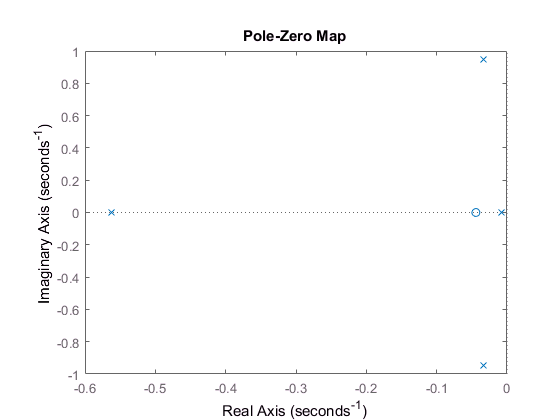

pzplot(sys)

Alternativ kann die Graphik auch manuell erstellt werden:

lambda = eig(A)

lambda =   -0.0329 + 0.9467i
  -0.0329 - 0.9467i
  -0.5627 + 0.0000i
  -0.0073 + 0.0000i


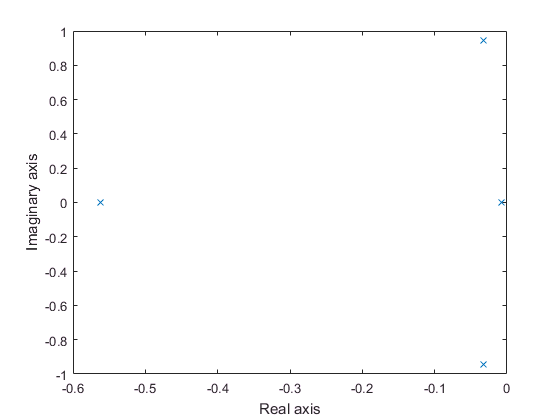

figure;
plot( real(lambda), imag(lambda),'x');
xlabel('Real axis'); ylabel('Imaginary axis');

if isstable(sys), disp('The system is stable');
else, disp('The system is unstable');
end

The system is stable


Da sich alle Pole auf der linken Hälfte der s-Ebene befinden ($\Re \text{ }\left\lbrace s_i \right\rbrace <0\text{ }\forall i$), ist das System stabil.

Die Open-Loop Sprung- und Impulsantworten sehen wie folgt aus:

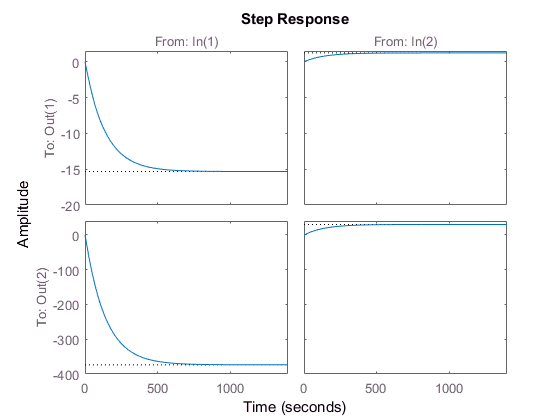

figure; step(sys)

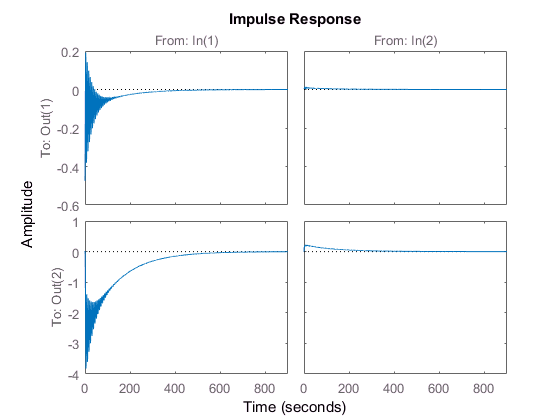

figure; impulse(sys)

## Aufgabe 3

`Angenommen das Querruder fällt aus. Kann der Pilot das Flugzeug noch in jede Fluglagebringen? Stimmt Ihre Antwort mit der Diskussion aus der Einleitung überein?`


$$Querruderausfall\Rightarrow Querruderausschlag\text{ }=\text{ }u_2 =0\text{ }\Leftrightarrow B∗u=\text{ }\left\lbrack \begin{array}{c}
u_1 \\
0
\end{array}\right\rbrack \Rightarrow B=\left\lbrack \begin{array}{c}
b_{11}  & 0\\
b_{21}  & 0\\
b_{31}  & 0\\
0 & 0
\end{array}\right\rbrack$$


B_Querruderausfall = [ B(:,1) , zeros(4,1) ]

B_Querruderausfall =     0.0073         0
   -0.4750         0
    0.1530         0
         0         0


sys_Querruderausfall = ss(A,B_Querruderausfall,C,D)


sys_Querruderausfall =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0558  -0.9968   0.0802   0.0415
   x2    0.598   -0.115  -0.0318        0
   x3    -3.05    0.388   -0.465        0
   x4        0   0.0805        1        0
 
  B = 
            u1       u2
   x1  0.00729        0
   x2   -0.475        0
   x3    0.153        0
   x4        0        0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



Q_S = ctrb(sys_Querruderausfall) % Steuerbarkeitsmatrix

Q_S =     0.0073         0    0.4853         0   -0.0985         0   -0.4044         0
   -0.4750         0    0.0541         0    0.2928         0   -0.0503         0
    0.1530         0   -0.2777         0   -1.3302         0    1.0327         0
         0         0    0.1148         0   -0.2733         0   -1.3066         0


%[Abar,Bbar,Cbar,T,k] = ctrbf(A,B_Querruderausfall,C)
rang_Q_S = rank(Q_S)

rang_Q_S = 4

if rang_Q_S == rank(A), disp('Given System is Controllable.');
else, disp('Given System is Uncontrollable');
end

Given System is Controllable.


Folglich ist das Flugzeug auch nach einem Querruderausfall steuerbar.

## Aufgabe 4

`Lassen sich durch die beiden Ausgänge alle Zustände beobachten? Angenommen alle Gyroskope im Flugzeug fallen aus und der Pilot schätzt jetzt den Rollwinkel über den Horizont ab. Kann der Pilot damit alle anderen Zustände beobachten?`

% Berechnung der Beobachtbarkeitsmatrix
Q_B = obsv(sys)

Q_B =          0    1.0000         0         0
         0         0         0    1.0000
    0.5980   -0.1150   -0.0318         0
         0    0.0805    1.0000         0
   -0.0051   -0.5952    0.0664    0.0248
   -3.0019    0.3787   -0.4676         0
   -0.5582    0.1013    0.0125   -0.0002
    1.8200    2.7673   -0.0354   -0.1246


%[Abar,Bbar,Cbar,T,k] = obsvf(A,B,C)
% Berechnung des Rangs
rang_Q_B = rank(Q_B)

rang_Q_B = 4

if rang_Q_B == rank(A), disp('Given System is Observable.');
else, disp('Given System is Unobservable');
end

Given System is Observable.



$$Gyroskop\text{ausfall}\Rightarrow Gyroskopmessung\text{ }=\mathbf{y}=\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack \text{ }\Leftrightarrow C∗\mathbf{x}=\text{ }\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack \Rightarrow C=\left\lbrack \begin{array}{c}
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0
\end{array}\right\rbrack$$



$$Rollwinkelbeobachtung\Rightarrow Rollwinkel\text{ }=x_4 \ne \text{ }0\Leftrightarrow C∗\left\lbrack \begin{array}{c}
0\\
0\\
0\\
x_4 
\end{array}\right\rbrack \Rightarrow C=\left\lbrack \begin{array}{c}
0 & 0 & 0 & 0\\
0 & 0 & 0 & c_{24} 
\end{array}\right\rbrack$$


C_Gyroskopausfall = [ zeros(1,4) ; C(2,:) ]

C_Gyroskopausfall =      0     0     0     0
     0     0     0     1


sys_Gyroskopausfall = ss(A,B,C_Gyroskopausfall,D)


sys_Gyroskopausfall =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0558  -0.9968   0.0802   0.0415
   x2    0.598   -0.115  -0.0318        0
   x3    -3.05    0.388   -0.465        0
   x4        0   0.0805        1        0
 
  B = 
            u1       u2
   x1  0.00729        0
   x2   -0.475  0.00775
   x3    0.153    0.143
   x4        0        0
 
  C = 
       x1  x2  x3  x4
   y1   0   0   0   0
   y2   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



% Berechnung der Beobachtbarkeitsmatrix
Q_B_Gyroskopausfall = obsv(sys_Gyroskopausfall)

Q_B_Gyroskopausfall =          0         0         0         0
         0         0         0    1.0000
         0         0         0         0
         0    0.0805    1.0000         0
         0         0         0         0
   -3.0019    0.3787   -0.4676         0
         0         0         0         0
    1.8200    2.7673   -0.0354   -0.1246


%[Abar,Bbar,Cbar,T,k] = obsvf(A,B,C)
% Berechnung des Rangs
rang_Q_B_Gyroskopausfall = rank(Q_B_Gyroskopausfall)

rang_Q_B_Gyroskopausfall = 4

if rang_Q_B_Gyroskopausfall == rank(A), disp('Given System is Observable.');
else, disp('Given System is Unobservable');
end

Given System is Observable.


Folglich ist das System auch trotz Gyroskopausfall weiterhin beobachtbar.

## Aufgabe 5

`Angenommen ein starker Seitenwind setzt während des neutralen Reiseflugs sprunghaft ein. Treffen Sie sinnvolle Annahmen wie die Zustände des Systems durch den Wind beeinflusst werden. Wie wird das Flugzeug darauf reagieren wenn kein weiterer Eingang zur Regelung verwendet wird und der Wind `

`(i) konstant selten seitlich weht, `

`(ii) es sich nur um eine kurze Böhe handelt? `

`Visualisieren und diskutieren Sie das Übergangsverhalten und das stationäre Verhalten aller Zustände in beiden Fällen.`

Die folgende Angabe für B_Seitenwind ist aus der Lösung übernommen - es sollte noch geklärt werden, woher diese Annahme stammt!

B_Seitenwind = [0.2, 0.1, 0, 0.01]';
sys_Seitenwind = ss(A,B_Seitenwind,eye(4),0)


sys_Seitenwind =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0558  -0.9968   0.0802   0.0415
   x2    0.598   -0.115  -0.0318        0
   x3    -3.05    0.388   -0.465        0
   x4        0   0.0805        1        0
 
  B = 
         u1
   x1   0.2
   x2   0.1
   x3     0
   x4  0.01
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



Falls der Wind konstant weht, ergibt sich die folgende **Sprungantwort**:

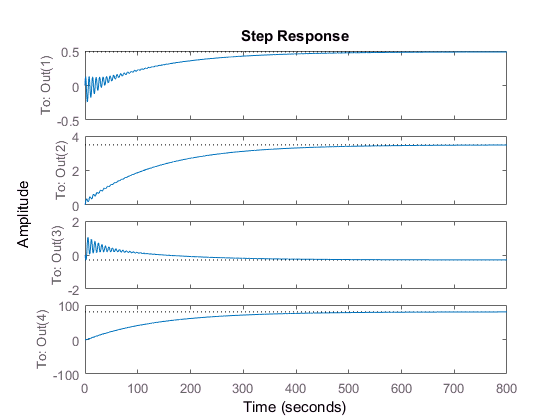

step(sys_Seitenwind)

Falls es sich jedoch nur um eine Windböe handelt, ergibt sich folgende **Impulsantwort**:

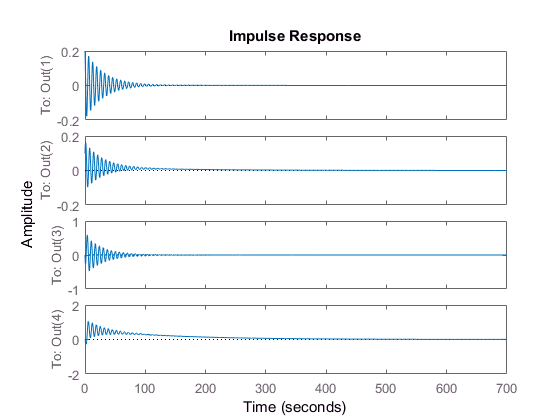

impulse(sys_Seitenwind)

## Aufgabe 6

`Angenommen der Pilot möchte eine Kursabweichung in horizontaler Ebene korrigieren (also den Gierwinkel) in dem nur das Seitenruder verwendet wird. Anstatt den Kurskreisel abzulesen orientiert sich der Pilot fälschlicherweise am Wendezeiger. Er verwendet wie üblich eine negative Einheitsrückführung für die Regelung. Ist mit drastischer Veränderung der Fluglage zu rechnen? Falls ja, würde eine positive Einheitsrückführung dies verhindern? Betrachten Sie dafür die Übertragungsfunktion des geschlossenen Regelkreises und geben diese aus.`

sys_A6 = ss(A,B(:,1), C, 0)  % Solution: ss(A,B(:,1), C(2,1) , 0) ?!


sys_A6 =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0558  -0.9968   0.0802   0.0415
   x2    0.598   -0.115  -0.0318        0
   x3    -3.05    0.388   -0.465        0
   x4        0   0.0805        1        0
 
  B = 
            u1
   x1  0.00729
   x2   -0.475
   x3    0.153
   x4        0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



tf_A6 = tf(sys_A6)


tf_A6 =
 
  From input to output...
          -0.475 s^3 - 0.2479 s^2 - 0.1187 s - 0.05633
   1:  ---------------------------------------------------
       s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
                  0.1148 s^2 - 0.2004 s - 1.373
   2:  ---------------------------------------------------
       s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
Continuous-time transfer function.



fb_A6a = feedback(tf_A6,[1 1], -1) % negative Einheitsrückführung


fb_A6a =
 
  From input to output...
         -0.475 s^3 - 0.2479 s^2 - 0.1187 s - 0.05633
   1:  ------------------------------------------------
       s^4 + 0.1608 s^3 + 0.8058 s^2 + 0.1926 s - 1.425
 
                0.1148 s^2 - 0.2004 s - 1.373
   2:  ------------------------------------------------
       s^4 + 0.1608 s^3 + 0.8058 s^2 + 0.1926 s - 1.425
 
Continuous-time transfer function.



if isstable(fb_A6a), display('No drastic changes');
else, display('Drastic changes');
end

Drastic changes


fb_A6b = feedback(tf_A6,[1 1], +1) % positive Einheitsrückführung


fb_A6b =
 
  From input to output...
        -0.475 s^3 - 0.2479 s^2 - 0.1187 s - 0.05633
   1:  ----------------------------------------------
       s^4 + 1.111 s^3 + 1.072 s^2 + 0.8307 s + 1.433
 
               0.1148 s^2 - 0.2004 s - 1.373
   2:  ----------------------------------------------
       s^4 + 1.111 s^3 + 1.072 s^2 + 0.8307 s + 1.433
 
Continuous-time transfer function.



if isstable(fb_A6b), display('No drastic changes');
else, display('Drastic changes');
end

Drastic changes


Das System wird also durch diesen Fehler instabil, unebhängig davon, ob eine positive oder negative Einheitsrückführung verwendet wurde.

## Aufgabe 7

`Angenommen der Pilot möchte eine Drehung um die Rollachse korrigieren (also den Rollwinkel) in dem nur das Querruder verwendet wird. Anstatt den Wendezeiger abzulesen orientiert sich der Pilot fälschlicherweise am Schiebewinkel (Es wir angenommen, dass der Pilot diesen nun beobachten kann). Er verwendet wie üblich eine negative Einheitsrückführung für die Regelung. Ist mit drastischer Veränderung der Fluglage zu rechnen? Falls ja, würde eine positive Einheitsrückführung dies verhindern? Verwenden Sie dafür die Pol-/Nullstellen Darstellung des geschlossenen Regelkreises und geben diese aus.`

C_A7 = [1, 0, 0, 0];
sys_A7 = ss(A, B(:,2), C_A7, 0);
tf_A7 = tf(sys_A7)


tf_A7 =
 
         0.003743 s^2 + 0.008461 s + 0.0008041
  ---------------------------------------------------
  s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
Continuous-time transfer function.



fb_A7a = feedback(tf_A7, 1, -1) % negative Einheitsrückführung


fb_A7a =
 
         0.003743 s^2 + 0.008461 s + 0.0008041
  ---------------------------------------------------
  s^4 + 0.6358 s^3 + 0.9426 s^2 + 0.5201 s + 0.004478
 
Continuous-time transfer function.



if isstable(fb_A7a), display('No drastic changes');
else, display('Drastic changes');
end

No drastic changes



fb_A7b = feedback(tf_A7, 1,+1) % positive Einheisrückführung


fb_A7b =
 
        0.003743 s^2 + 0.008461 s + 0.0008041
  --------------------------------------------------
  s^4 + 0.6358 s^3 + 0.9351 s^2 + 0.5032 s + 0.00287
 
Continuous-time transfer function.



if isstable(fb_A7b), disp('No drastic changes');
else, disp('Drastic changes');
end

No drastic changes


Das System ist also weiterhin stabil, unabhängig von einer positiven oder negativen Einheitsrückführung.

## Aufgabe 8

`Überprüfen Sie durch eine passende Abbildung, ob sich das Flugzeug mithilfe des Querruders besser um die Gierachse drehen lässt als mit dem Seitenruder (bei vergleichbaren Steuerausschlägen). `

sys_Seitenruder = ss(A,-B(:,1), C(1,:), 0) % Seitenruder / rudder; Use negativ B to ensure same input and output direction (otherwise its mirrored)


sys_Seitenruder =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0558  -0.9968   0.0802   0.0415
   x2    0.598   -0.115  -0.0318        0
   x3    -3.05    0.388   -0.465        0
   x4        0   0.0805        1        0
 
  B = 
             u1
   x1  -0.00729
   x2     0.475
   x3    -0.153
   x4         0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



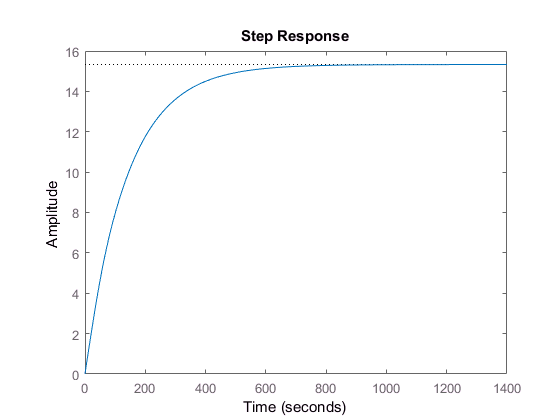

step(sys_Seitenruder)

sys_Querruder = ss(A,B(:,2), C(2,:), 0) % Querruder / aileron


sys_Querruder =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0558  -0.9968   0.0802   0.0415
   x2    0.598   -0.115  -0.0318        0
   x3    -3.05    0.388   -0.465        0
   x4        0   0.0805        1        0
 
  B = 
            u1
   x1        0
   x2  0.00775
   x3    0.143
   x4        0
 
  C = 
       x1  x2  x3  x4
   y1   0   0   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



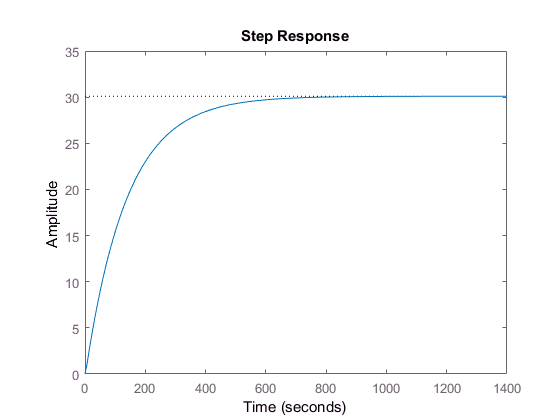

step(sys_Querruder)

Wie zu erkennen ist, lässt sich das Flugzeug besser um die Gierachse mithilfe des Querruders drehen (ca. die Doppelte Amplitude).

## Aufgabe 9

`Gibt es für den Piloten eine Möglichkeit die Seiten- und Querruder so zu bewegen, dass der Eingang an den Ausgängen nicht zu beobachten ist (für das ungeregelte System)? Der Autopilot verwendet jetzt den Regler `$U\left(s\right)=K\left(s\right)Y\left(s\right)$` mit `$K\left(s\right)=I_{2x2}$`. Gibt es jetzt für den geschlossenen Regelkreis Frequenzen die vom Eingang nicht zum Ausgang durchdringen?`

Open-Loop System:

tf_sys = tf(sys) % Original system


tf_sys =
 
  From input 1 to output...
          -0.475 s^3 - 0.2479 s^2 - 0.1187 s - 0.05633
   1:  ---------------------------------------------------
       s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
                  0.1148 s^2 - 0.2004 s - 1.373
   2:  ---------------------------------------------------
       s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
  From input 2 to output...
       0.00775 s^3 - 0.0005112 s^2 + 0.008701 s + 0.00453
   1:  ---------------------------------------------------
       s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
                 0.1436 s^2 + 0.02739 s + 0.1106
   2:  ---------------------------------------------------
       s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
Continuous-time transfer function.



inv_zeros = tzero(tf_sys)

inv_zeros =   -0.0329 + 0.9467i
  -0.0329 - 0.9467i
  -0.5627 + 0.0000i
  -0.0443 + 0.0000i
  -0.0073 + 0.0000i


T = freqresp(tf_sys, inv_zeros)

T = 
(:,:,1) =

   1.0e+14 *

   0.8456 + 1.3956i   0.0276 + 0.0045i
  -7.3233 + 0.1120i  -0.0798 + 0.0968i


(:,:,2) =

   1.0e+14 *

   0.8456 - 1.3956i   0.0276 - 0.0045i
  -7.3233 - 0.1120i  -0.0798 - 0.0968i


(:,:,3) =

   1.0e+14 *

   0.0813 + 0.0000i  -0.0094 + 0.0000i
  -5.9953 + 0.0000i   0.6891 + 0.0000i


(:,:,4) =

   2.9960 + 0.0000i  -0.2409 + 0.0000i
  79.3026 + 0.0000i  -6.3776 + 0.0000i


(:,:,5) =

   1.0e+15 *

   0.0555 + 0.0000i  -0.0045 + 0.0000i
   1.3711 + 0.0000i  -0.1104 + 0.0000i


svd_T = zeros(1, length(T));
for i = 1:length(T)
    svd_T(i) = svd(T(i));
end
disp(svd_T)

   1.0e+14 *

    1.6318    7.3242    0.0279    0.1254    1.6318



if any(svd_T < 1e-5), disp('There is a possibility for the pilot');
else, disp('There is no possibility for the pilot');
end

There is no possibility for the pilot


Jetzt mit negativer Einheitsrückführung:

fb_sys = feedback(tf_sys, eye(2), -1) % negative Einheitsrückführung


fb_sys =
 
  From input 1 to output...
                                                                                             
       -0.475 s^7 - 0.5499 s^6 - 0.7914 s^5 - 0.6546 s^4 - 0.3427 s^3 - 0.1528 s^2           
                                                                                             
                                                                      - 0.03107 s - 0.0002182
                                                                                             
   1:  --------------------------------------------------------------------------------------
                                                                                             
       s^8 + 0.7966 s^7 + 1.876 s^6 + 1.544 s^5 + 1.148 s^4 + 0.7922 s^3 + 0.2343 s^2        
                                                                                             
                                                                      + 0.02937 s + 0.0002016
                    

for i=1:length(inv_zeros)
    T = evalfr(fb_sys, inv_zeros(i))
    if any(svd(T) < 1), disp('There is a possibility for the pilot');
    else, disp('There is no possibility for the pilot');
    end
end

T =    1.3633 - 0.3128i   0.0225 - 0.0296i
  -0.3458 + 5.6705i  -0.4339 - 0.0581i


There is a possibility for the pilot


T =    1.3633 + 0.3128i   0.0225 + 0.0296i
  -0.3458 - 5.6705i  -0.4339 + 0.0581i


There is a possibility for the pilot


T =     0.2680   -0.0087
   -8.1406    1.0882


There is a possibility for the pilot


T =    -1.2580    0.1012
  -33.2985    2.6779


There is a possibility for the pilot


T =    -0.9566    0.0672
  -20.1059    1.8420


There is a possibility for the pilot


Folglich gibt es keine Möglichkeit für den Piloten mit dem Open-Loop System, jedoch ist es mit einer negativen Rückführung möglich.

## Aufgabe 10

`Angenommen, der Pilot ist verwirrt und weiß nicht mehr welcher Eingang zum Seiten bzw. Querruder gehört. Berechnen Sie hierfür den Relative Gain Array (RGA) der Übertragungsfunktion des Flugzeugs und erklären Sie wie man daran ablesen kann, welcher Eingang zu welchem Ausgang gehört. (Hinweis: Der RGA muss für niedrige Frequenzen am Eingang betrachtet werden).`

rga = tf_sys * inv(tf_sys)'


rga =
 
  From input 1 to output...
                                                                                             
       0.0008691 s^19 - 0.9877 s^18 + 0.3485 s^17 - 3.098 s^16 + 0.8961 s^15 - 3.232 s^14    
                                                                                             
               + 0.7164 s^13 - 0.8551 s^12 + 0.09591 s^11 + 0.5232 s^10 - 0.09422 s^9        
                                                                                             
               + 0.2458 s^8 - 0.02233 s^7 - 0.02301 s^6 + 0.001178 s^5 - 0.01164 s^4         
                                                                                             
                                    + 0.0005998 s^3 - 3.133e-06 s^2 - 3.178e-08 s + 1.986e-10
                                                                                             
   1:  ---------------------------------------------------------------------------------------
                      

freqresponse = freqresp(rga, logspace(0,10, 11)) % 0, 10, 100, ... 1e10

freqresponse = 
(:,:,1) =

   1.0e+02 *

  -0.0058 - 0.0170i   0.5729 + 0.2524i
   0.0635 + 0.0195i  -1.9995 + 1.1791i


(:,:,2) =

  -0.9860 - 0.0173i   0.8269 + 0.3939i
   0.0222 - 0.0258i   0.9802 + 0.1153i


(:,:,3) =

  -0.9876 + 0.0843i   0.7270 + 5.3127i
   0.0162 - 0.0023i   0.9871 + 0.0110i


(:,:,4) =

  -0.9876 + 0.8688i   0.7260 +53.2646i
   0.0161 - 0.0002i   0.9871 + 0.0011i


(:,:,5) =

   1.0e+02 *

  -0.0099 + 0.0869i   0.0073 + 5.3266i
   0.0002 - 0.0000i   0.0099 + 0.0000i


(:,:,6) =

   1.0e+03 *

  -0.0010 + 0.0869i   0.0007 + 5.3266i
   0.0000 - 0.0000i   0.0010 + 0.0000i


(:,:,7) =

   1.0e+04 *

  -0.0001 + 0.0869i   0.0001 + 5.3266i
   0.0000 - 0.0000i   0.0001 + 0.0000i


(:,:,8) =

   1.0e+05 *

  -0.0000 + 0.0869i   0.0000 + 5.3266i
   0.0000 - 0.0000i   0.0000 + 0.0000i


(:,:,9) =

   1.0e+06 *

  -0.0000 + 0.0869i   0.0000 + 5.3266i
   0.0000 - 0.0000i   0.0000 + 0.0000i


(:,:,10) =

   1.0e+07 *

  -0.0000 + 0.0869i   0.0000 + 5.3266i
   0.0000 - 0.00

## Aufgabe 11

`Im Landeanflug möchte der Pilot das Flugzeug steuern während die Höhe sich verringert. Die Systemmatrix A lautet im Landeanflug wie folgt, während sich die Auswirkungen der Steuersignale und die Messungen nicht ändern:`

A = ...
[-0.0428, -0.9863,  0.0844,  0.0391;...
  0.6083, -0.1726, -0.0417, -0.0097;...
 -2.6894,  1.0542, -0.2743, -0.0243;...
 -0.6040, -2.8825,  0.3116, -0.1760 ];

`Ist das Flugzeug stabil (ohne Piloteneingriff)? Ist das Flugzeug steuerbar mit (i) nur Seitenruder, (ii) nur Querruder?`

 sys_Landeanflug_Seitenruder = ss(A, B(:,1), C, 0)


sys_Landeanflug_Seitenruder =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0428  -0.9863   0.0844   0.0391
   x2   0.6083  -0.1726  -0.0417  -0.0097
   x3   -2.689    1.054  -0.2743  -0.0243
   x4   -0.604   -2.882   0.3116   -0.176
 
  B = 
            u1
   x1  0.00729
   x2   -0.475
   x3    0.153
   x4        0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



 if isstable(sys_Landeanflug_Seitenruder), disp('System is stable');
 else, disp('System is not stable');
 end

System is stable


Q_S_Landeanflug_Seitenruder = ctrb(sys_Landeanflug_Seitenruder) % Steuerbarkeitsmatrix

Q_S_Landeanflug_Seitenruder =     0.0073    0.4811   -0.0918   -0.4096
   -0.4750    0.0800    0.2886   -0.0510
    0.1530   -0.5623   -1.0896    0.8729
         0    1.4125   -0.9451   -0.9496


rang_Q_S_Landeanflug_Seitenruder = rank(Q_S_Landeanflug_Seitenruder)

rang_Q_S_Landeanflug_Seitenruder = 4

if rang_Q_S_Landeanflug_Seitenruder == rank(A), disp('Given System is Controllable.');
else, disp('Given System is Uncontrollable');
end

Given System is Controllable.


Das gegebene System ist also für den Landeanflug mit Seitenruder stabil und steuerbar.

sys_Landeanflug_Querruder = ss(A, B(:,2), C, 0)


sys_Landeanflug_Querruder =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0428  -0.9863   0.0844   0.0391
   x2   0.6083  -0.1726  -0.0417  -0.0097
   x3   -2.689    1.054  -0.2743  -0.0243
   x4   -0.604   -2.882   0.3116   -0.176
 
  B = 
            u1
   x1        0
   x2  0.00775
   x3    0.143
   x4        0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



 if isstable(sys_Landeanflug_Querruder), disp('System is stable');
 else, disp('System is not stable');
 end

System is stable


Q_S_Landeanflug_Querruder = ctrb(sys_Landeanflug_Querruder) % Steuerbarkeitsmatrix

Q_S_Landeanflug_Querruder =          0    0.0044    0.0053   -0.0060
    0.0077   -0.0073    0.0050    0.0028
    0.1430   -0.0311   -0.0116   -0.0058
         0    0.0222    0.0048   -0.0221


rang_Q_S_Landeanflug_Querruder = rank(Q_S_Landeanflug_Querruder)

rang_Q_S_Landeanflug_Querruder = 4

if rang_Q_S_Landeanflug_Querruder == rank(A), disp('Given System is Controllable.');
else, disp('Given System is Uncontrollable');
end

Given System is Controllable.


Ebenso ist es für den Landeanflug mit Querruder stabil und steuerbar.